## Stillbilder

clear
%image = double(imread('baboon.png'));
image = double(imread('boat.png'));
%image = double(imread('woodgrain.png'));

[x,y] = size(image);



p = distribution2d(image);
H1 = entropyOfDistribution(p)

H1 = 7.1238

#### Parentropi horisontellt


$$H\left(X_{i,j} ,X_{i+1,j} \right)$$



data = reshape(image,1,x*y);

horizontal_data = zeros(size(data));

horizontal_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
    horizontal_data(1,i) = data(1,i) - data(1,i-1);
end

% Tar bort negativa värden
horizontal_data = minshift(horizontal_data);

p2 = distribution2d(horizontal_data);
H_hori = entropyOfDistribution(p2)

H_hori = 4.9665

#### Parentropi vertikalt


$$H\left(X_{i,j} ,X_{i,j+1} \right)$$


% Transponera bilden ger vertikala grannar
data = reshape(image',1,x*y);
vertical_data = zeros(size(data));

vertical_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
    vertical_data(1,i) = data(1,i) - data(1,i-1);
end
% Tar bort negativa värden
vertical_data = minshift(vertical_data);

p3 = distribution2d(vertical_data);
H_vert = entropyOfDistribution(p3)

H_vert = 5.2062

#### Betingad


$$\left.H\left(X_{i+1,j} \right|X_{i,j} \right)$$


H_hori_cond = H_hori - H1

H_hori_cond = -2.1573

 H(Xi,j+1 | Xi,j) 

H_vert_cond = H_vert - H1

H_vert_cond = -1.9175

#### Huffmankodning


$$Y_{i,j} =X_{i,j} -P_{i,j}$$


l = huffman(p)

l = 7.1468

l2 = huffman(p2)

l2 = 5.0032

l3 = huffman(p3)

l3 = 5.2430


data = padarray(image,[1 1],128, 'both');

newimage = zeros(size(data));
for x = 2:size(data,1) 
    for y = 2:size(data,2) 
        newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
    end
end
newimage = newimage(2:end-1,2:end-1);
newimage = minshift(newimage);
[row,col] = size(newimage);
data_l4 = reshape(newimage,row*col,1);

p4 = distribution2d(data_l4);
l4 = huffman(p4)

l4 = 6.0568


H_adj = entropyOfDistribution(p4)

H_adj = 6.0297

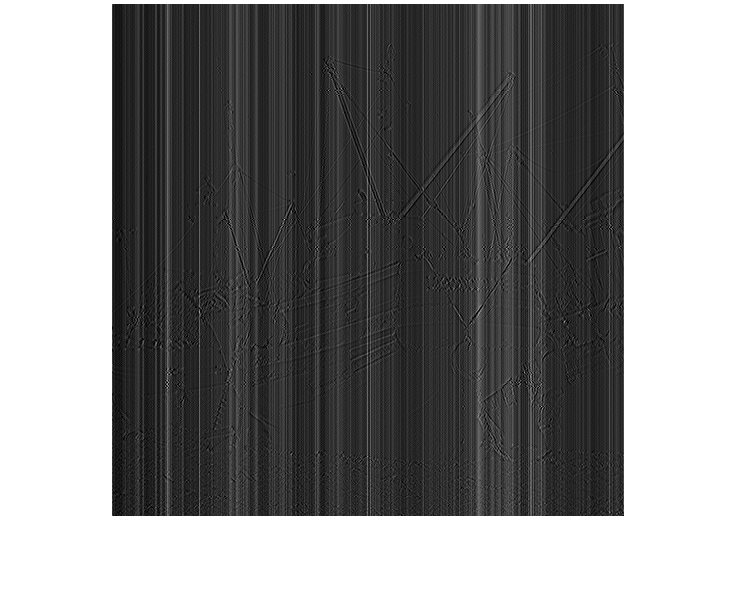

imshow(newimage/256) %kanske rätt output?